close all; clc; clear all;

## Exercise 2

Vx = 30;
lf = 1.56;
lr = 1.64;
Ca = 246994;
Izz = 4964;
m = 2041;
ts = 0.01;
Ac = [0 Vx Vx 0; 0 0 0 1; 0 0 -2*Ca/(m*Vx) (Ca*(lr-lf)/(m*Vx^2))-1; 0 0 Ca*(lr-lf)/Izz -Ca*(lr^2+lf^2)/(Izz*Vx)];
Bc = [0 0; 0 0; Ca/(m*Vx) Ca/(m*Vx); Ca*lf/Izz -Ca*lr/Izz];
C = [0 0 1 lf/Vx; 0 0 1 -lr/Vx; 0 0 0 0; 0 0 0 0];
D = [1 0; 0 1; 1 0; 0 1];

sys_c = ss(Ac,Bc,C,D);
sys_d = c2d(sys_c, ts);
A = sys_d.A;
B = sys_d.B;
Cc = sys_d.C;
Dd = sys_d.D;

#### Part B

E = [1 0 0 0; 0 1 0 0];
F = zeros(2,2);
G = null([A - eye(size(A)), B, zeros(size(B)); E, F, -eye(size(F))]);
% Extract basis vectors for Gx, Gy, Gz
Gx = G(1:4, 1:2);
Gu = G(5:6, 1:2);
Gz = G(7:8, 1:2);
Gx = Gx/Gz;
Gu = Gu/Gz;
Gz = Gz/Gz;

x0 = [0;0;0;0];
ref = [5;0];
v = ref;
% System Dimensions
[n,m] = size(B);

yub = deg2rad([8, 8, 30, 6]');
ylb = deg2rad([-8, -8, -30, -6]');

C = [Cc
    -Cc];
D = [Dd
    -Dd];
y = [yub
    -ylb];

R = eye(2);
Q = E'*E;

% LQR Solution
[K,P,~] = dlqr(A,B,Q,R);

% Prediction Horizon
N = 70;    

Ox = zeros(1,n);
Ov = zeros(1,m);
oy = 0;

% Terminal Constraints (O_infinity)
[Ox,Ov,oy] = calc_Oinf(A,B,C,D,K,y, Gx, Gu);

% Pad Ox with Zeros
Ox = [zeros(length(oy),N*m+(N-1)*n) Ox];

% QP, Sparse Formulation
In = eye(N);
In1 = diag(ones(N-1,1),-1);

H = blkdiag(kron(In,R),kron(eye(N-1),Q),P);
f = zeros(N*(n+m),1);
% fnew = zeros(N*(n+m),1);  
% fnew = [repmat(R*Gu, N, 1); repmat(Q*Gx, (N-1), 1); P*Gx];
fnew = [kron(ones(N, 1), R*Gu); kron(ones(N-1, 1), Q*Gx); P*Gx];

E  = [kron(In,B) kron(In1,A)-eye(N*n)];
gx = [-A;zeros((N-1)*n,n)];

Y  = [kron(In,D) kron(In1,C)];
yx = [-C;zeros((N-1)*length(y),n)];
yc = kron(ones(N,1),y);

out = sim('HW_4_Q2.slx');

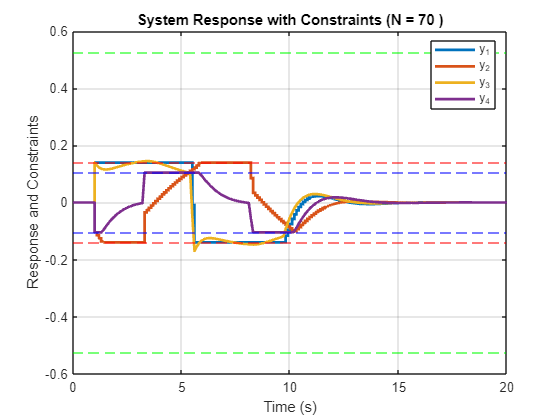

% Plots
t = out.tout;
x = out.x';
u = out.u';
out_y = out.y';

figure()
grid on;
stairs(t, out_y(1,:), 'LineWidth', 2); hold on;
stairs(t, out_y(2,:), 'LineWidth', 2);
plot(t, out_y(3,:), 'LineWidth', 2);
plot(t, out_y(4,:), 'LineWidth', 2);

% Adding constraints with labels
yline(deg2rad(8), 'r--');
yline(deg2rad(-8), 'r--');
yline(deg2rad(30), 'g--');
yline(deg2rad(-30), 'g--');
yline(deg2rad(6), 'b--');
yline(deg2rad(-6), 'b--');

xlabel('Time (s)');
ylabel('Response and Constraints');
title('System Response with Constraints (N = 70)');
legend({'y_1', 'y_2', 'y_3', 'y_4'}, 'Location', 'best');
grid on; 
hold off;

System Response with Command Governor from Homework 3:

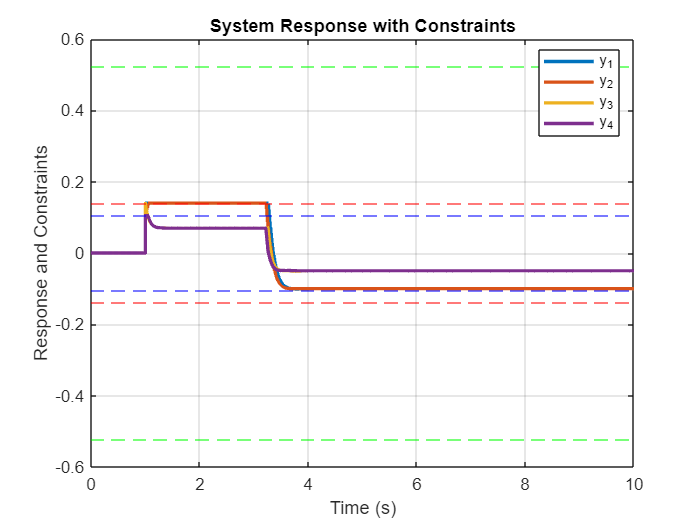

In the command governor strategy, the system response is smooth and cautious, avoiding any breach of constraints, suggesting a conservative control approach. This ensures robust constraint satisfaction but may not exploit the full performance potential of the system.

The MPC approach shows a more ambitious attempt to balance constraint satisfaction with performance. Initially, it tests the constraint limits, resulting in a dynamic response with noticeable fluctuations. After this aggressive phase, the MPC stabilizes, similarly maintaining the constraints, indicating that it leverages its predictive capabilities to optimize the control inputs within the set boundaries.

Overall, while the command governor prioritizes safety margins, the MPC seeks a closer approach to the constraints for potential performance benefits, which is evident in the more variable response patterns before settling.

subplot(2,1,1)
stairs(t,x(1,:))
hold on
xlabel('$t$','Interpreter',"latex")
ylabel('$x_1$','Interpreter',"latex")
title('States')

subplot(2,1,2)
stairs(t,x(2,:))
hold on
xlabel('$t$','Interpreter',"latex")
ylabel('$x_2$','Interpreter',"latex")

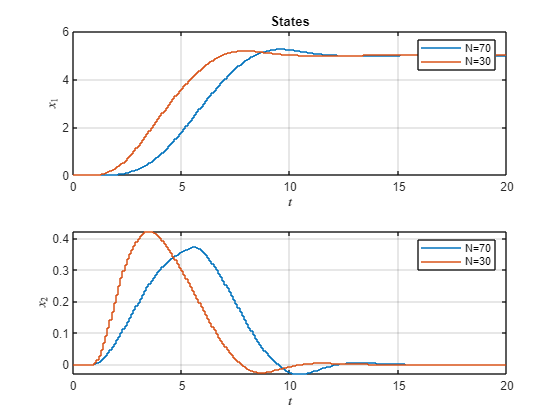

N = 30;
Ox = zeros(1,n);
Ov = zeros(1,m);
oy = 0;
[Ox,Ov,oy] = calc_Oinf(A,B,C,D,K,y, Gx, Gu);
Ox = [zeros(length(oy),N*m+(N-1)*n) Ox];
% QP, Sparse Formulation
In = eye(N);
In1 = diag(ones(N-1,1),-1);

H = blkdiag(kron(In,R),kron(eye(N-1),Q),P);
% f = zeros(N*(n+m),1);
% fnew = zeros(N*(n+m),1);
fnew = [repmat(R*Gu, N, 1); repmat(Q*Gx, (N-1), 1); P*Gx];

E  = [kron(In,B) kron(In1,A)-eye(N*n)];
gx = [-A;zeros((N-1)*n,n)];

Y  = [kron(In,D) kron(In1,C)];
yx = [-C;zeros((N-1)*length(y),n)];
yc = kron(ones(N,1),y);

out = sim('HW_4_Q2.slx');

t = out.tout;
x = out.x';
u = out.u';
y = out.y';
x1 = out.x1';
u1 = out.u1';
y1 = out.y1';


subplot(2,1,1)
stairs(t,x(1,:))
hold off; grid on
xlabel('$t$','Interpreter',"latex")
ylabel('$x_1$','Interpreter',"latex")
legend("N=70","N=30")
title('States')

subplot(2,1,2)
stairs(t,x(2,:))
hold off; grid on
xlabel('$t$','Interpreter',"latex")
ylabel('$x_2$','Interpreter',"latex")
legend("N=70","N=30")

The MPC implementation with a longer horizon (N = 70) ensured all constraints were met throughout the maneuv.er The system's response visualized in the plot above, demonstrated the effectiveness of MPC in adhering to the constraints while achieving the target reference.

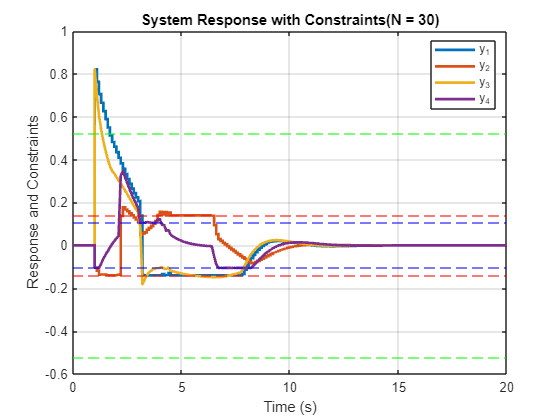

figure()
grid on;
stairs(t, y(1,:), 'LineWidth', 2); hold on;
stairs(t, y(2,:), 'LineWidth', 2);
plot(t, y(3,:), 'LineWidth', 2);
plot(t, y(4,:), 'LineWidth', 2);

% Adding constraints with labels
yline(deg2rad(8), 'r--');
yline(deg2rad(-8), 'r--');
yline(deg2rad(30), 'g--');
yline(deg2rad(-30), 'g--');
yline(deg2rad(6), 'b--');
yline(deg2rad(-6), 'b--');

xlabel('Time (s)');
ylabel('Response and Constraints');
title('System Response with Constraints(N = 30)');
legend({'y_1', 'y_2', 'y_3', 'y_4'}, 'Location', 'best');
grid on; 
hold off;

Reducing the horizon to M= 30 compromised the MPC's ability to satisfy constraints, particularly during transient responses. The plot revealed more pronounced oscillations and overshoots, highlighting the importance of a suitable horizon length in constraint satisfaction.

#### Ramp Input, N = 30

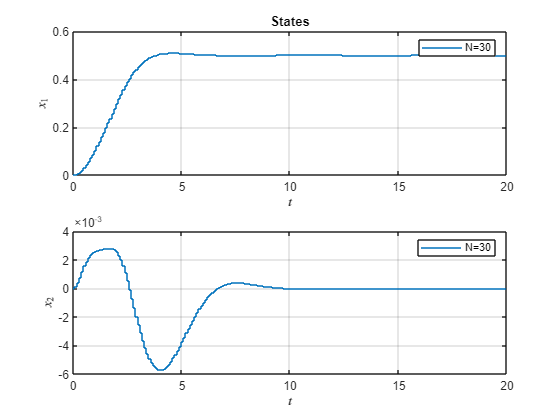

figure
subplot(2,1,1)
stairs(t,x1(1,:))
grid on
xlabel('$t$','Interpreter',"latex")
ylabel('$x_1$','Interpreter',"latex")
legend("N=30")
title('States')

subplot(2,1,2)
stairs(t,x1(2,:))
grid on
xlabel('$t$','Interpreter',"latex")
ylabel('$x_2$','Interpreter',"latex")
legend("N=30")

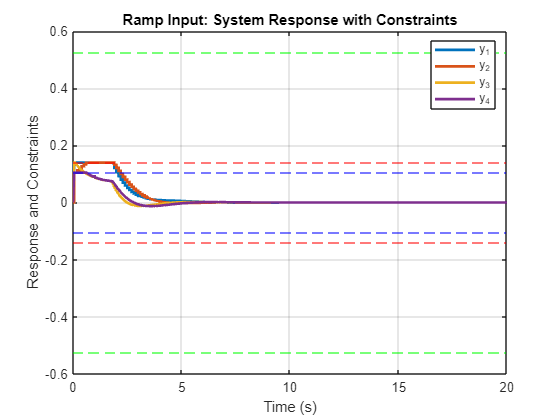

figure
grid on;
stairs(t, y1(1,:), 'LineWidth', 2); hold on;
stairs(t, y1(2,:), 'LineWidth', 2);
plot(t, y1(3,:), 'LineWidth', 2);
plot(t, y1(4,:), 'LineWidth', 2);

% Adding constraints with labels
yline(deg2rad(8), 'r--');
yline(deg2rad(-8), 'r--');
yline(deg2rad(30), 'g--');
yline(deg2rad(-30), 'g--');
yline(deg2rad(6), 'b--');
yline(deg2rad(-6), 'b--');

xlabel('Time (s)');
ylabel('Response and Constraints');
title('Ramp Input: System Response with Constraints');
legend({'y_1', 'y_2', 'y_3', 'y_4'}, 'Location', 'best');
grid on; 
hold off;

Introducing a ramp input improved the MPC's performance with a shorter horizon. As shown in plots, the system response was smoother, and constraint satisfaction was notably better compared to the step input scenario, emphasizing the  benefit of input shaping in constrained control. The ramp input moderates the control demands placed on the system, helping the MPC maintain constraint satisfaction even with a reduced horizon length.

# Auxiliary Functions

function [Ox,Ov,oy] = calc_Oinf(A_ol,B_ol,C_ol,D_ol,K,y,Gx, Gu)

% Steady-State Manifold
% G = null([A_ol-eye(size(A_ol)) B_ol]);
% Gx = G(1:size(A_ol,2),:);
% Gu = G(size(A_ol,2)+1:end,:);

% Closed Loop System
A = A_ol-B_ol*K;
B = B_ol*(Gu+K*Gx);
C = C_ol-D_ol*K;
D = D_ol*(Gu+K*Gx);

% Steady-State Constraints
eps = 0.05;
Hss = [0*C C*Gx+D];
hss = (1-eps)*y;

% 0-step Constraint Admissible Set
H0 = [C D];
h0 = y;

Oinf = Polyhedron([Hss;H0],[hss;h0]);

while isempty(h0)~=1
    % Plot Polyhedron
    % Oinf.plot
    % xlabel('$x_1$','Interpreter','latex')
    % ylabel('$x_2$','Interpreter','latex')
    % zlabel('$v$','Interpreter','latex')
    % axis equal
    % pause(0.01)
    
    % Update Constraints
    H1 = H0*[A B; zeros(size(B')) eye(size(B,2))];
    h1 = h0;
    
    % Eliminate Redundant Rows
    [H1,h1] = elim_redundancies(Oinf,H1,h1);
    
    % Update the Polyhedron
    Oinf = Polyhedron([Oinf.A; H1],[Oinf.b; h1]);

    % Reinitialize Iteration
    H0 = H1;
    h0 = h1;
end
% Oinf Constraints
Ox = Oinf.A(:,1:4);
Ov = Oinf.A(:,5:6);
oy = Oinf.b;
end

function [H_nred,h_nred] = elim_redundancies(poly,H,h)
% Nonredundant Constraints
H_nred = [];
h_nred = [];

for i = 1:length(h)
    % Check Redundancy for each individual row
    f = -H(i,:)';
    
    A = [poly.A
         H((1:length(h))~=i,:)];
    
    b = [poly.b
         h((1:length(h))~=i,:)];
    
    % Solve LP
    [~,fval,flag]=linprog(f,A,b,[],[],[],[],optimoptions('linprog','Display','none'));
    
    if flag == -3 || -fval>h(i)
        % Constraint is not redundant
        H_nred = [H_nred;H(i,:)];
        h_nred = [h_nred;h(i)];
    end
    
end

end